%Code to declare parameters
no_runs = 0;
fs = 10000;

global Ts 
Ts = 1 / fs;
Sph = 630e3;
f = 50;
V1 = 10500;
V1ph = V1/sqrt(3);
V2 = 0.4e3;
V2ph = V2/sqrt(3);
% Primary Winding Resistance
R1 = 0.04612771;
% Secondary Winding Resistance
R2 = 0.0000669427;
% Primary Leakage Inductance
L1 = 0.3203609;
% Secondary Leakage Inductance
L2 = 0.000464923;
% Magnetization Resistance
Rm = 101146.7891;
% Magnetization Inductance
Lm = 86.89985;
%simulation time
time_to_simulate = 0.2;
%Primary and secondary windings
turns1 = 262;
turns2 = 10;

global Ploads
Ploads  = 10e3;
Qload = 274.611e3;
ishealthy = false;
istest = true;
global triggerTimes
triggerTimes = 0.02 : 0.02 : time_to_simulate;
global shortturns
shortturns = 0.02 : 0.02 : 0.99;
phases = 1 : 1 : 3;
sides = 1 : 1 : 2;
global sections
sections = 1 : 1 : 3;
%create_folders();
data_size = length(phases)*length(sides)*length(shortturns)*length(sections)*length(triggerTimes);

section = 1

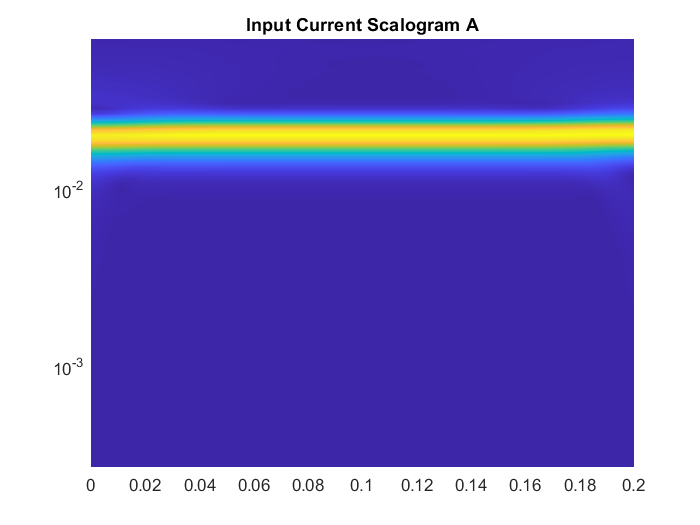

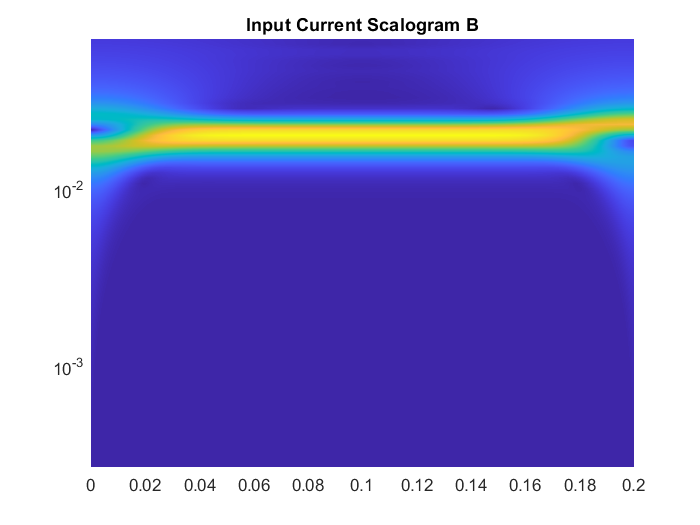

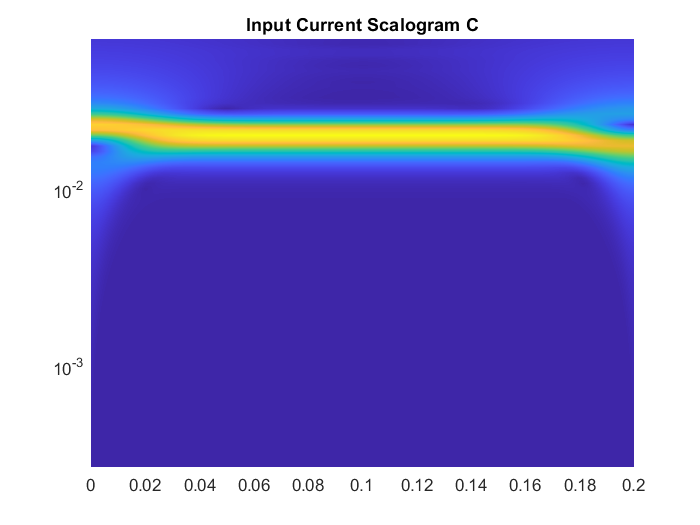

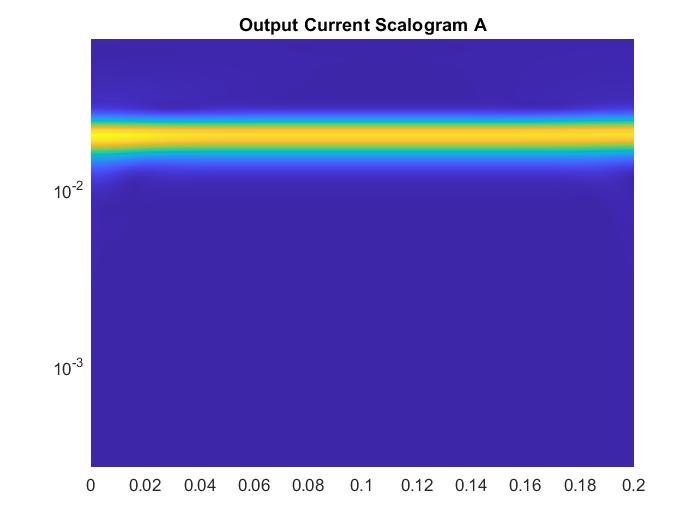

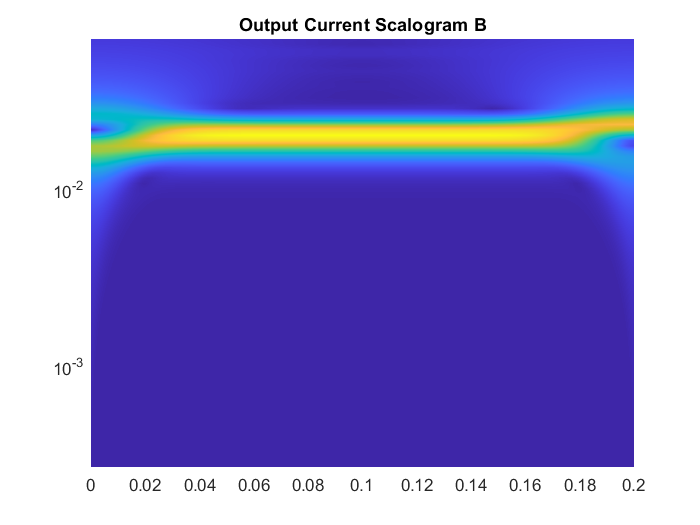

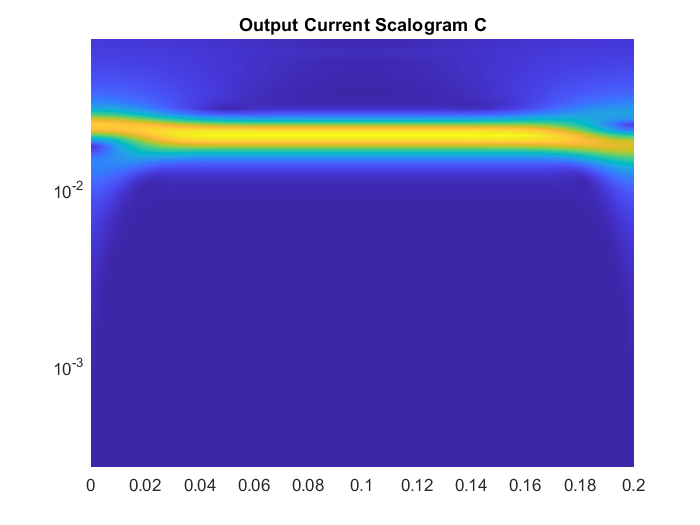

filepath = "C:\Users\Edwin\Desktop\Career\Research\Transformer Inter-turn\images"


for P = 100e3
    Pload = P;
    
    if ishealthy == true
        triggerTime = 3;
        run PhaseAcode.mlx;
        run PhaseBcode.mlx;
        run PhaseCcode.mlx;
       
        sim_model = sim("newfinal.slx")
        
        run processdata.mlx;
        %run displayresults.mlx;
    else         
       %{ 
for tr = 1:length(triggerTimes)
        triggerTime = triggerTimes(tr);
        % Loop over percentage shorts
        for ph = 1:length(phases)
            phaseunit = phases(ph);
            
            % Loop over the phases
            for y = 1:length(sides)
                side = sides(y);
                
                % Loop over the sides
                for z = 1:length(shortturns)
                    shortturn = shortturns(z);
                    
                    % Loop over the winding sections
                    for m = 1:length(sections)
                        section = sections(m);
       %}
            triggerTime = 0.01;
            phaseunit = 1;
            side = 2;
            shortturn = 0.2;
            section = 1


       
                        
                    run PhaseAcode.mlx;
                    run PhaseBcode.mlx;
                    run PhaseCcode.mlx;
                    sim_model = sim('newfinal.slx');
                    run processdata.mlx;
                    end
                 end

                            
%{          
            end
        end    
        end        
    end
end

%}




